## Program for analysing kinematics of multibody systems

Plan of action:

- Generate input data structure based on the example of slider crank

- Generate constraints and it derivatives (e.g., Newton-Raphson requires constraint vector and it's Jacobian).

- Solve system using NR and advance in time. Store data.

- After solution, make some ilustrative plots.

## Example: 

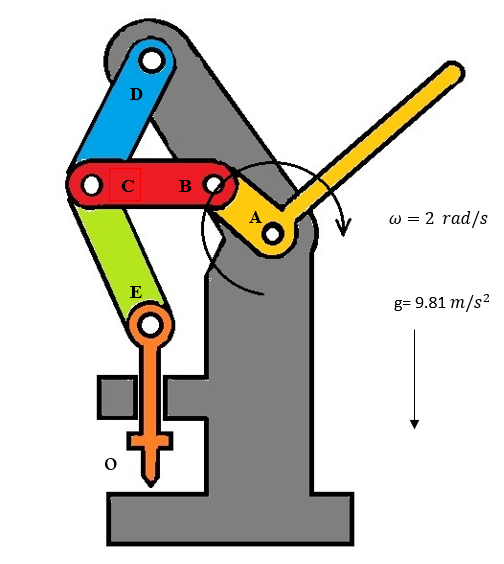

## **Information about this:**

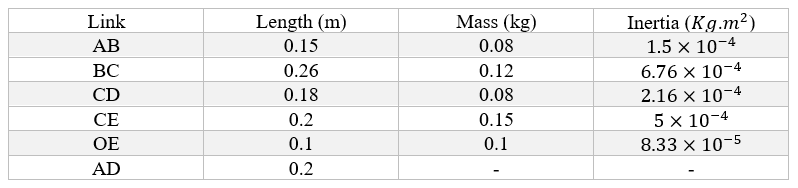

## **Body numbering:**

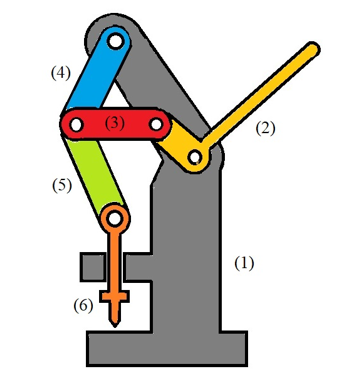

## **Local coordinate frames:**

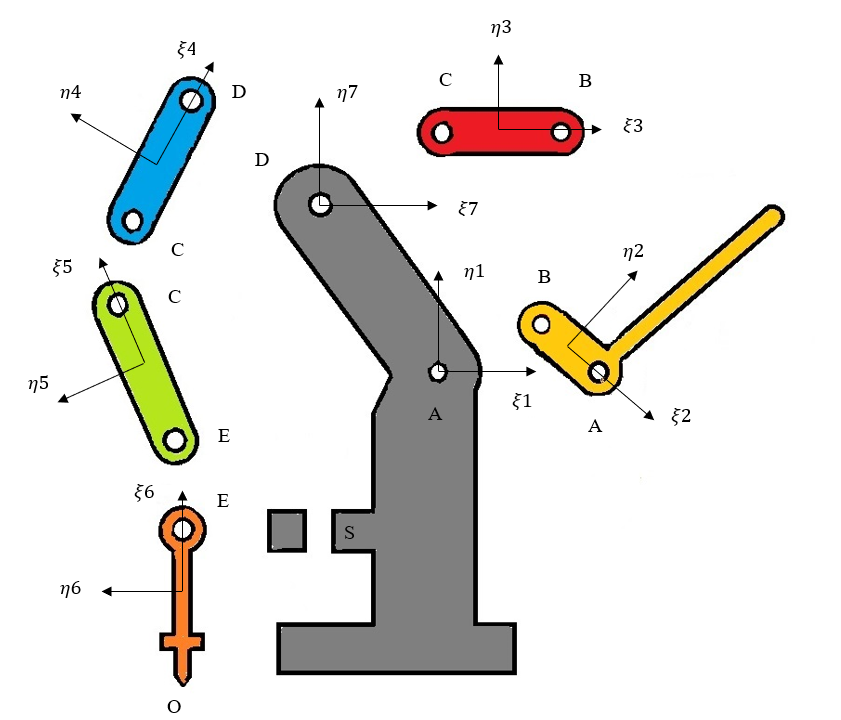

Data from the user

- Bodies and their coordinate frames.

- Joints and their characteristic points

- Solver settings

### Bodies and coordinates

clc;clear;close all;
mbs = init_mbs();
mbs = add_body(mbs, "ground", 0, 0, 0);
mbs = add_body(mbs, "ground_D", 0.15, 0.132, 0 );
mbs = add_body(mbs, "ground_S", 0.15, -0.132, 0 );
mbs = add_body(mbs, "AB", -0.1, 0.1, -deg2rad(30));
mbs = add_body(mbs, "BC", -0.15, 0.12, deg2rad(20));
mbs = add_body(mbs, "CD", -0.12, 0.1, deg2rad(15));
mbs = add_body(mbs, "CE", -0.25, 0.11, deg2rad(25));
mbs = add_body(mbs, "OE", -0.6)

mbs = struct with fields:
     bodies: [1×8 struct]
     joints: [1×1 struct]
         nq: 24
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


### Joints and characteristic points

Vectors that points to joint locations are in local coordinate frame. They do not change locations in time.

mbs = add_revolute(mbs, "revA", "ground", [0; 0], "AB", [0.075, 0.0]);
mbs = add_revolute(mbs, "revB", "AB", [-0.075; 0], "BC", [0.13, 0.0]);
mbs = add_revolute(mbs, "revC", "BC", [-0.13; 0], "CD", [-0.09, 0.0]);
mbs = add_revolute(mbs, "revC", "CD", [-0.09; 0], "CE", [0.1, 0.0]);
mbs = add_revolute(mbs, "revE", "CE", [-0.1; 0], "OE", [0.05, 0.0]);
mbs = add_revolute(mbs, "revD", "CD", [0.09; 0], "ground_D", [0.15, 0.132]);
% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);
mbs = add_simple_joint(mbs, "ground_D_x", "ground_D", "x", 0.15);
mbs = add_simple_joint(mbs, "ground_D_y", "ground_D", "y", 0.132);
mbs = add_simple_joint(mbs, "ground_D_angle", "ground_D", "fi", 0);
mbs = add_simple_joint(mbs, "ground_S_x", "ground_S", "x", 0.15);
mbs = add_simple_joint(mbs, "ground_S_y", "ground_S", "y", -0.132);
mbs = add_simple_joint(mbs, "ground_S_angle", "ground_S", "fi", 0);


mbs = add_simple_joint(mbs, "slidertranslation", "OE", "x", 0.15);
mbs = add_simple_joint(mbs, "sliderrotation", "OE", "fi", 0);

% Driving constraint for the crank
om = 2; % rad/s
mbs = add_driving_joint(mbs, "ABrotation", "AB", "fi", @(t)-deg2rad(30) - om * t);

### Basic checking

fprintf("System has %d bodies and %d coordinates.\n", length(mbs.bodies), mbs.nq)

System has 8 bodies and 24 coordinates.


fprintf("Number of the joints:\n\tRevolute: %d\n\tPrismatic: %d\n", ...
    length(mbs.joints.revolute), length(mbs.joints.prismatic))

Number of the joints:
	Revolute: 6
	Prismatic: 0


fprintf("\tSimple: %d\n\tDriving: %d\n", length(mbs.joints.simple), length(mbs.joints.driving))

	Simple: 11
	Driving: 1


fprintf("In total %d DOF are constrained!\n", mbs.nc)

In total 24 DOF are constrained!


### **Coordinates (initial values)**

They vere defined in the mbs.bodies. We want to put them together in single vector.

q0 = initial_position(mbs);

### Constraints vector C

t0 = 0.0;
C = constraints(mbs, q0, t0);

### Solution using fsolve

Now we can check the code with function fsolve

tic
q0_correct = fsolve(@(y)constraints(mbs, y, 0.0), q0);


Solver stopped prematurely.

fsolve stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+02.



toc

Elapsed time is 1.680895 seconds.


% disp([q0, q0_correct])
C0 = constraints(mbs, q0_correct, t0)

C0 =    -0.0045
   -0.0020
   -0.0045
   -0.0020
   -0.0045
   -0.0020
    0.0001
    0.0000
    0.0001
    0.0000


### Jacobian of constraints

We need it for position and velocity analysis (and we will need it for euqations of motion).

Cq = constraints_dq(mbs, q0);

Now we can solve kinematic analysis on position (initial) using Newton-Raphson

tic
[q0_correct_NR, NR_iter] = ...
    NR_method(@(y)constraints(mbs, y, 0.0), ...
    @(y)constraints_dq(mbs, y), q0, 1e-8)

q0_correct_NR = 	1.0e+03 *

         0
         0
         0
    0.0001
    0.0001
         0
    0.0001
   -0.0001
         0
   -0.0001


NR_iter = -1

toc

Elapsed time is 0.050244 seconds.


Simple check

disp([q0, q0_correct, q0_correct_NR])

   1.0e+03 *

         0    0.0000         0
         0    0.0000         0
         0         0         0
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
         0    0.0000         0
    0.0001    0.0001    0.0001
   -0.0001   -0.0001   -0.0001
         0         0         0
   -0.0001   -0.0001   -0.0001
    0.0001    0.0000    0.0000
   -0.0005   -0.0005   -0.0005
   -0.0001    0.0000    0.0000
    0.0001    0.0001    0.0001
    0.0003    0.0036    0.0785
   -0.0001    0.0002    0.0002
    0.0001    0.0002    0.0002
    0.0003    0.0004    0.1204
   -0.0003    0.0002    0.0002
    0.0001    0.0003   -0.0000
    0.0004    0.0043    1.8302
   -0.0006    0.0002    0.0001
         0    0.0004   -0.0001
         0    0.0000         0



C0_NR = constraints(mbs, q0_correct_NR, t0)

C0_NR =          0
         0
   -0.0162
   -0.0057
   -0.0384
   -0.0184
    0.0207
    0.0166
   -0.0015
    0.0039


### Kinematic analysis on position

h = 0.05;
t_end = 1;
tol = 1e-8;
[T, Q, Qp, Qpp, niter] = kinematic_analysis_acc(mbs, q0, h, t_end, tol);

Very basic postprocessing

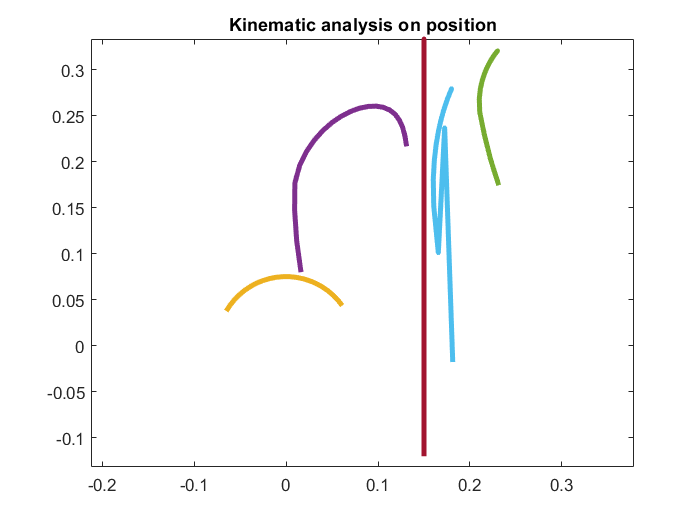

plot(Q(:, 4), Q(:, 5), Q(:, 7), Q(:, 8), ...
    Q(:, 10), Q(:, 11),Q(:, 13), Q(:, 14), Q(:, 16), Q(:, 17),...
    Q(:, 19), Q(:, 20), Q(:, 22), Q(:, 23),'LineWidth', 3)
axis equal
title('Kinematic analysis on position')

Now similar plot for velocity

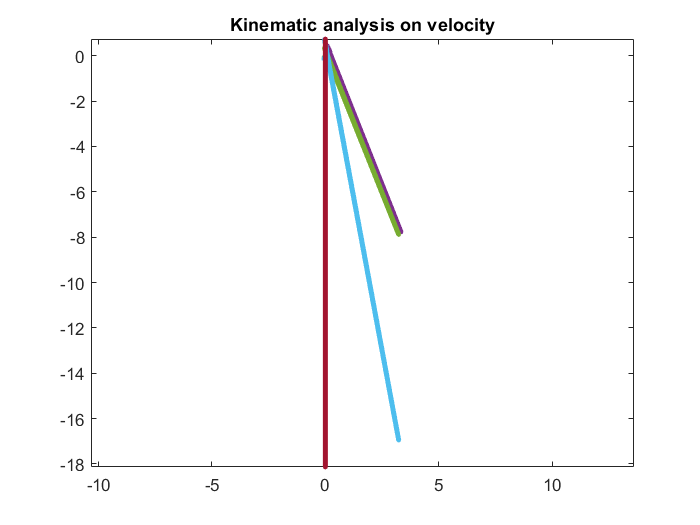

plot(Qp(:, 4), Qp(:, 5), Qp(:, 7), Qp(:, 8), ...
   Qp(:, 10), Qp(:, 11),Qp(:, 13), Qp(:, 14), Qp(:, 16), Qp(:, 17),...
   Qp(:, 19), Qp(:, 20), Qp(:, 22), Qp(:, 23),'LineWidth', 3)
axis equal
title('Kinematic analysis on velocity')

plot for acceleration

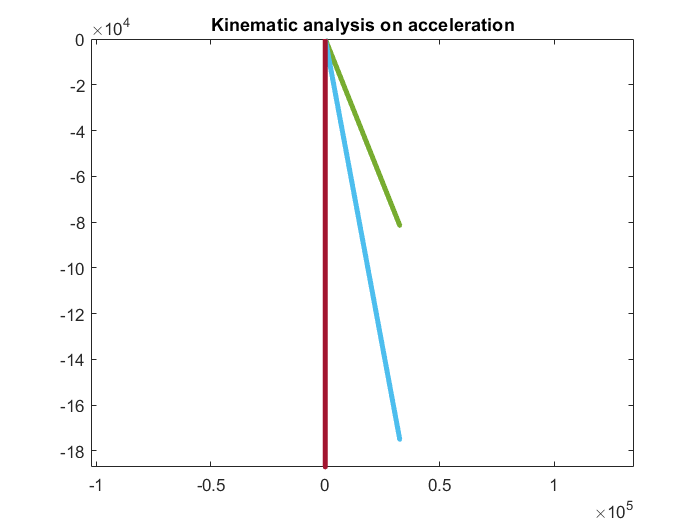

plot(Qpp(:, 4), Qpp(:, 5), Qpp(:, 7), Qpp(:, 8), ...
    Qpp(:, 10), Qpp(:, 11),Qpp(:, 13), Qpp(:, 14), Qpp(:, 16), Qpp(:, 17),...
   Qpp(:, 19), Qpp(:, 20), Qpp(:, 22), Qpp(:, 23),'LineWidth', 3)
axis equal
title('Kinematic analysis on acceleration')

Number of NR iterations

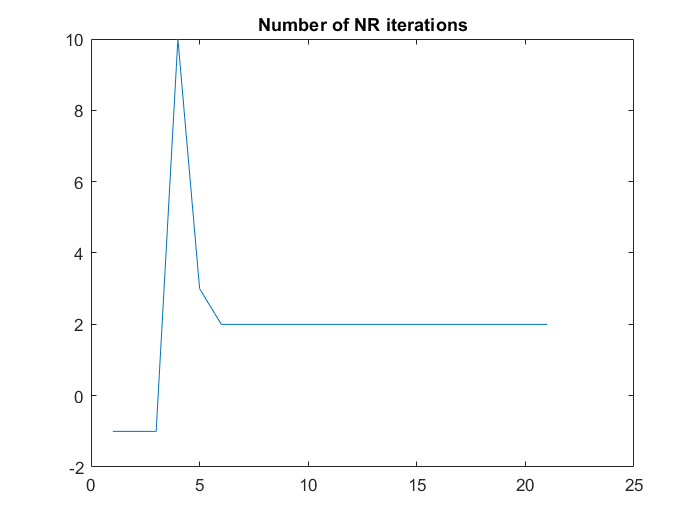

plot(niter)
title('Number of NR iterations')